% Clear all variables from the workspace to start fresh
clear all

% Close all open figure windows
close all

% Set the random number generator seed to 5
% This ensures reproducibility of random processes (e.g., for sampling)
rng(5)


% Here we are going to load the created map data.

% Define the variable g with a value of 1, map selector
g = 1;

% Load the occupancy map data for the specified map number (g)
% The variable 'Map' is loaded from the file
load("2D\occupancy_map_data" + g + ".mat");

% Assign the loaded map to a variable named 'map'
map = Map;

% Load the occupancy map for the specified map number (g)
% The variable 'omap' is loaded from the file
load("2D\occupancy_map" + g + ".mat");

% Create an occupancyMap object from the loaded occupancy map data (omap)
Map = occupancyMap(omap);


% Here we are going to set up the start and end parameters.
% start_orientation and goal_orientation parameters will determine how the
% algorithm will connect to it. They have to be given in radians.

% Define the starting position (x, y) and orientation (in radians) of the robot
start_x = 5;
start_y = 8;
start_orientation = 0;

% Define the goal position (x, y) and orientation (in radians) for the robot
goal_x = 17;
goal_y = 17;
goal_orientation = 0;

% Combine the start position and orientation into a single pose variable
robot_pose = [start_x, start_y, start_orientation];

% Combine the goal position and orientation into a single pose variable
goal_pose = [goal_x, goal_y, goal_orientation];



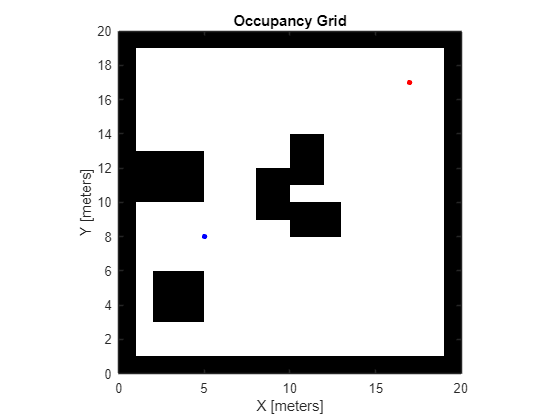

% Lidar setup
lidar = rangeSensor;

% VFH (Vector Field Histogram) setup
vfh = controllerVFH;
vfh.UseLidarScan = true;

% It is important that the safety distance is greater than the UAV speed
vfh.SafetyDistance = 0.5;

% Limits for range readings, specified as a 2-element vector with elements
% measured in meters. The range readings specified when calling the object
% are considered only if they fall within the distance limits. Use the lower
% distance limit to ignore false positives from poor sensor performance at 
% lower ranges. Use the upper limit to ignore obstacles that are too far 
% from the vehicle.
vfh.DistanceLimits = [0.5 2];

% Create a figure to show the map
MapFigure = figure;

% Create a figure for VFH visualization (not used in this segment)
VFHFigure = figure;

% Display the map in the MapFigure
figure(MapFigure);
show(Map)

% Hold the current figure to overlay additional plots
hold on

% Plot the robot's starting position on the map with a blue marker
plot(robot_pose(1), robot_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2);

% Plot the goal position on the map with a red marker
plot(goal_pose(1), goal_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2, 'Color', "red");

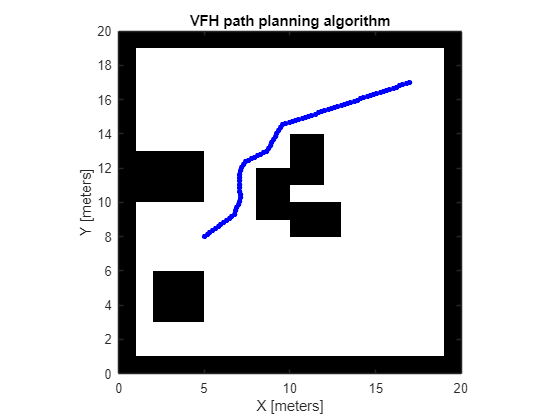

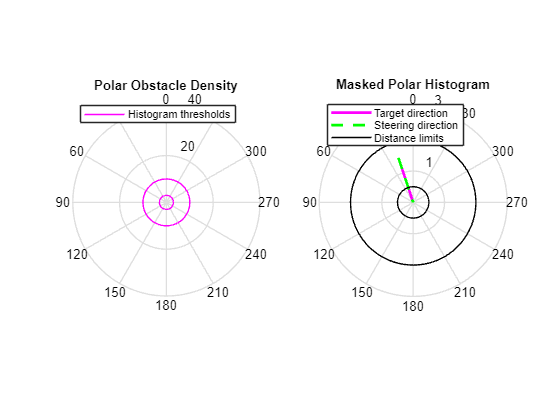

% Set the initial value of the trigger to true
trigger = true;

% Set the maximum number of steps for the algorithm
test = 100;

% Initialize the counter to keep track of the number of steps
counter = 1;

% We are going to repeat the process until the trigger turns false. The trigger can
% be turned false in two ways: 
% 1. When the algorithm reaches the goal.
% 2. When the algorithm exceeds the maximum number of steps specified by the test variable.
% If the counter variable becomes greater than the test variable, the trigger will turn false.

while trigger
    % Lidar measurements
    [ranges, angles] = lidar(robot_pose, Map);

    % Geometry about the angles to be appropriate
    % Calculate the Euclidean distance between the start and end coordinates
    tavolsag_x = goal_pose(1) - robot_pose(1);
    tavolsag_y = goal_pose(2) - robot_pose(2);

    % Use atan2d to get the corresponding angle in all four quadrants
    goal_angle = atan2d(tavolsag_y, tavolsag_x);
    
    % Correct the angle with the original orientation of the UAV
    goal_angle = deg2rad(goal_angle) + deg2rad(0 - start_orientation);
    
    % Scan the virtual environment
    scan = lidarScan(ranges, angles);
    
    % Rotate the scan to be according to the drone orientation
    rotateScan = transformScan(scan, [0, 0, robot_pose(3) + deg2rad(0 - start_orientation)]);

    % Use the VFH algorithm to calculate the required steering angle in radians
    steeringDir = vfh(rotateScan, goal_angle);
    
    % Convert the steering angle to degrees
    new_deg = rad2deg(steeringDir);
    
    % Show the VFH algorithm output in the VFHFigure
    figure(VFHFigure)
    show(vfh)
    
    % Drone parameter setup
    v_drone = 0.2; % Speed of the drone in m/s (initially set to 0.2, can be adjusted dynamically)

    % Update the robot's orientation to the new steering direction
    robot_pose(3) = new_deg;
    
    % Update the robot's position based on the new orientation and speed
    robot_pose(1) = robot_pose(1) + cosd(new_deg) * v_drone;
    robot_pose(2) = robot_pose(2) + sind(new_deg) * v_drone;
    
    % Plot the updated robot position on the map
    figure(MapFigure);
    plot(robot_pose(1), robot_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2);
    title("VFH path planning algorithm")
    drawnow

    % Stop the algorithm if the UAV is within the threshold distance to the goal
    if abs(tavolsag_x) < 0.4 && abs(tavolsag_y) < 0.3
        trigger = false;
    end

    % Stop the algorithm if it does not find a solution within the maximum number of steps
    if counter > test
        break;
    end

    % Increment the step counter
    counter = counter + 1;
end